addpath 'E:\MATLAB'
addpath 'E:'\MATLAB\Images\
ImageNames={'baby.png';'bird.png';'woman.png';'monarch.png';'airplane.png';'arctichare.png';'peppers1.tiff';'peppers2.png';'foreman.png'};
%ImageNames={'kodim01.png';'kodim02.png';'kodim03.png';'kodim04.png';'kodim05.png';'kodim06.png';'kodim07.png';'kodim08.png';'kodim09.png';'kodim10.png';'kodim11.png';'kodim12.png';'kodim13.png';'kodim14.png';'kodim15.png'};
%ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'aerial9.tiff';'aerial10.tiff'};
PSNR_R=zeros(size(ImageNames,1),1);
PSNR_G=zeros(size(ImageNames,1),1);
PSNR_B=zeros(size(ImageNames,1),1);
SSIM_R=zeros(size(ImageNames,1),1);
SSIM_G=zeros(size(ImageNames,1),1);
SSIM_B=zeros(size(ImageNames,1),1);
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=imread(string);
    %A=imgaussfilt(A);
    R = double(A(:,:,1)); % Red channel
    G = double(A(:,:,2)); % Green channel
    B = double(A(:,:,3)); % Blue channel
    [SR3,SR3G,SR3B]= KipkoechSuperResolution (R,G,B);
    SRimage=cat(3,uint8(SR3),uint8(SR3G),uint8(SR3B));
    PSNR_R(i)=psnr(uint8(SR3),uint8(R));
    PSNR_G(i)=psnr(uint8(SR3G),uint8(G));
    PSNR_B(i)=psnr(uint8(SR3B),uint8(B));
    SSIM_R(i)=ssim(uint8(SR3),uint8(R));
    SSIM_G(i)=ssim(uint8(SR3G),uint8(G));
    SSIM_B(i)=ssim(uint8(SR3B),uint8(B));
end
toc

Elapsed time is 5.610907 seconds.


T=table(ImageNames,PSNR_R,PSNR_G,PSNR_B,SSIM_R,SSIM_G,SSIM_B)

T = 9×7 table
        ImageNames        PSNR_R    PSNR_G    PSNR_B    SSIM_R     SSIM_G     SSIM_B 
    __________________    ______    ______    ______    _______    _______    _______

    {'baby.png'      }    36.473    36.621    36.464    0.95973    0.95862     0.9483
    {'bird.png'      }    36.145     36.47    36.219    0.97599    0.97568    0.96484
    {'woman.png'     }    31.755    31.788    31.844    0.95307    0.95566    0.95588
    {'monarch.png'   }    32.978    32.712    32.588     0.9631    0.96075    0.95288
    {'airplane.png'  }    32.693    30.797    32.799    0.94803     0.9427    0.92661
    {'arctichare.png'}    40.045    42.262    43.145    0.98321    0.98354      0.984
    {'peppers1.tiff' }    31.823    30.293     31.92    0.8

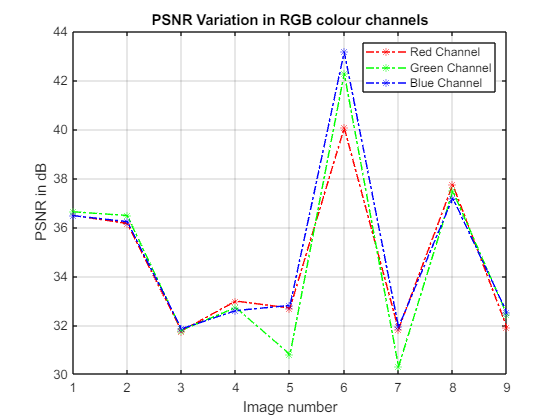

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\factor2.xlsx'];
writetable(T,path_format)
n=1:size(ImageNames,1);
figure;
plot(n,PSNR_R,'-.r*',n,PSNR_G,'-.g*',n,PSNR_B,'-.b*')
grid on
ylabel ('PSNR in dB')
xlabel ('Image number')
title ('PSNR Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel')

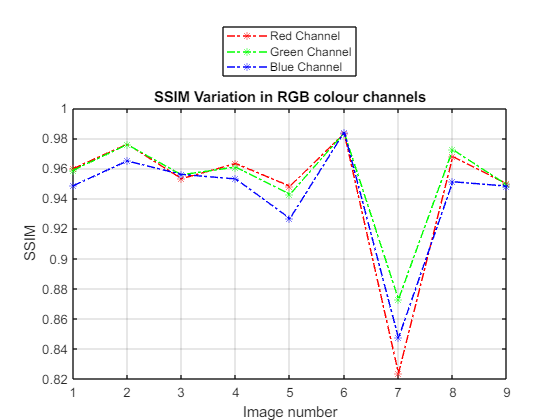

figure;
plot(n,SSIM_R,'-.r*',n,SSIM_G,'-.g*',n,SSIM_B,'-.b*')
grid on
ylabel ('SSIM')
xlabel ('Image number')
title ('SSIM Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel', ...
    'Location','northoutside')

function [SR3,SR3G,SR3B]= KipkoechSuperResolution (R,G,B)
k=2;
LR=KipkoechDownSampling(R,k); %down sampling
LRG=KipkoechDownSampling(G,k);
LRB=KipkoechDownSampling(B,k);
LRPrefiltered=KipkoechCubicBSplinesPrefilter(LR); %prefiltering
LRGPrefiltered=KipkoechCubicBSplinesPrefilter(LRG);
LRBPrefiltered=KipkoechCubicBSplinesPrefilter(LRB);
InterpolatedImageR=KipkoechBSplinesInterpolation(LRPrefiltered,k); %interpolation
InterpolatedImageG=KipkoechBSplinesInterpolation(LRGPrefiltered,k);
InterpolatedImageB=KipkoechBSplinesInterpolation(LRBPrefiltered,k);
SRinitialR=KipkoechDWT(InterpolatedImageR,R);
SRinitialG=KipkoechDWT(InterpolatedImageG,G);
SRinitialB=KipkoechDWT(InterpolatedImageB,B);
% Downsample SR
LR1=KipkoechDownSampling(SRinitialR,k);
LR1G=KipkoechDownSampling(SRinitialG,k);
LR1B=KipkoechDownSampling(SRinitialB,k);
[M,N]=size(LR1);
HF=zeros(M,N);
%Back Projection Step 1
E1=LR-LR1;
E1G=LRG-LR1G;
E1B=LRB-LR1B;
E1i=weightedguidedfilter(E1,E1,7,0.0001);
E1iG=weightedguidedfilter(E1G,E1G,7,0.0001);
E1iB=weightedguidedfilter(E1B,E1B,7,0.0001);
E11=double(E1i).*2;
E11G=double(E1iG).*2;
E11B=double(E1iB).*2;
BP1=idwt2(E11,HF,HF,HF,'db1');
BP1G=idwt2(E11G,HF,HF,HF,'db1');
BP1B=idwt2(E11B,HF,HF,HF,'db1');
SR1=SRinitialR+BP1;
SR1G=SRinitialG+BP1G;
SR1B=SRinitialB+BP1B;
% Back Projection Step 2
LR2=KipkoechDownSampling(SR1,k);
LR2G=KipkoechDownSampling(SR1G,k);
LR2B=KipkoechDownSampling(SR1B,k);
E2=LR-LR2;
E2G=LRG-LR2G;
E2B=LRB-LR2B;
E2i=weightedguidedfilter(E2,E2,7,0.0001);
E2iG=weightedguidedfilter(E2G,E2G,7,0.0001);
E2iB=weightedguidedfilter(E2B,E2B,7,0.0001);
E22=double(E2i).*2;
E22G=double(E2iG).*2;
E22B=double(E2iB).*2;
BP2=idwt2(E22,HF,HF,HF,'db1');
BP2G=idwt2(E22G,HF,HF,HF,'db1');
BP2B=idwt2(E22B,HF,HF,HF,'db1');
SR2=SR1+BP2;
SR2G=SR1G+BP2G;
SR2B=SR1B+BP2B;
% Back Projection Step 3
LR3=KipkoechDownSampling(SR2,k);
LR3G=KipkoechDownSampling(SR2G,k);
LR3B=KipkoechDownSampling(SR2B,k);
E3=LR-LR3;
E3G=LRG-LR3G;
E3B=LRB-LR3B;
E3i=weightedguidedfilter(E3,E3,7,0.0001);
E3iG=weightedguidedfilter(E3G,E3G,7,0.0001);
E3iB=weightedguidedfilter(E3B,E3B,7,0.0001);
E33=double(E3i).*2;
E33G=double(E3iG).*2;
E33B=double(E3iB).*2;
BP3=idwt2(E33,HF,HF,HF,'db1');
BP3G=idwt2(E33G,HF,HF,HF,'db1');
BP3B=idwt2(E33B,HF,HF,HF,'db1');
SR3=SR2+BP3;
SR3G=SR2G+BP3G;
SR3B=SR2B+BP3B;
end

